load('Double_Red._with95CI.mat');
data_xes = xes; % same for all files
data_patchxes = patchxes; % same for all files
one_mean = C;
one_ci = dataPatch;

load('Double_Green._with95CI.mat')
two_mean = C;
two_ci = dataPatch;

load('Double_Blue._with95CI.mat')
three_mean = C;
three_ci = dataPatch;




% plot results
f1=figure()

f1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [584 495 560 420]
       Units: 'pixels'

  Show all properties


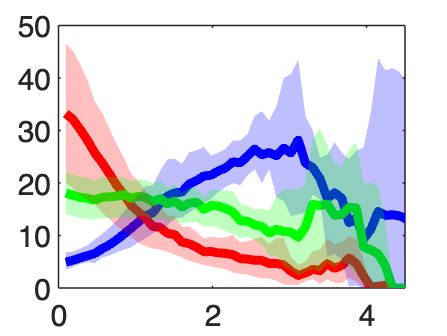


plot(data_xes, three_mean, 'b', 'linewidth',3)
 hold on
plot(data_xes, one_mean, 'r', 'linewidth',3)
plot(data_xes, two_mean,  'g', 'linewidth',3)

patch(data_patchxes, three_ci, 'b', "FaceAlpha", 0.25, 'LineStyle', 'none')
patch(data_patchxes, one_ci, 'r', "FaceAlpha", 0.25, 'LineStyle', 'none')
patch(data_patchxes, two_ci,'g', "FaceAlpha", 0.25, 'LineStyle', 'none')


ylim([0 50])
xlim([0, 4.5])